# Make a Datastore

Instructions are in the task pane to the left. Complete and submit each task one at a time.

# Handwriting Sample Files

Samples of each letter were collected from many different volunteers. Some provided more than one sample of each letter. Each sample was saved in a separate file and all the files were stored in one folder. The file names have the form

`user003_B_2.txt`

This file would contain the second sample of the letter B written by the volunteer designated “user003”.

You can use wildcards to make a datastore to files or folders matching a particular pattern.

`ds` `=` `datastore``(``"data*.xlsx"``)``;`

The handwriting data files have names of the form `user003_B_2.txt`.

## Task 1

Use the `datastore` function to make a datastore to all files containing the letter M. These files have `_M_` in their name and a `.txt` extension. Store the datastore in a variable called `letterds`.

clear;clc
letterds = datastore("*_M_*.txt")

letterds =   TabularTextDatastore with properties:

                      Files: {
                             ' ...\machinelearning_course_files\Data\user001_M_1.txt';
                             ' ...\machinelearning_course_files\Data\user002_M_1.txt';
                             ' ...\machinelearning_course_files\Data\user003_M_1.txt'
                              ... and 146 more
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
          ReadVariableNames: true
              VariableNames: {'Time', 'X', 'Y' ... and 1 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: ','
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format Properties:
            TextscanFormats: {'%f', '%f', '%f' ... an

You can use the `read` function to import the data from a file in the datastore.

`data` `=` `read``(``ds``)``;`

Using the `read` function the first time will import the data from the first file. Using it a second time will import the data from the second file, and so on.

## Task 2

Import the data from the first file into a table called `data`.

data=read(letterds)

data = 28×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    34806    0.775    0.228    0.042
    34808    0.775    0.227    0.255
    34808    0.775    0.227    0.255
    34825    0.774    0.221     0.44
    34833    0.774    0.214    0.569
    34850    0.773    0.199    0.745
    34866    0.772    0.188      0.8
    34886    0.772    0.176    0.851
    34900    0.773    0.173     0.88
    34944    0.777    0.194    0.894
    34949    0.778    0.201    0.896
    34975    0.784    0.228    0.899
    34995    0.789    0.249    0.923
    35000     0.79    0.251    0.931
    35018    0.791    0.248    0.995
    35058     0.79    0.209        1


## Task 3

Visualize the data by plotting the `X` variable of `data` on the horizontal axis and the `Y` variable on the vertical axis.

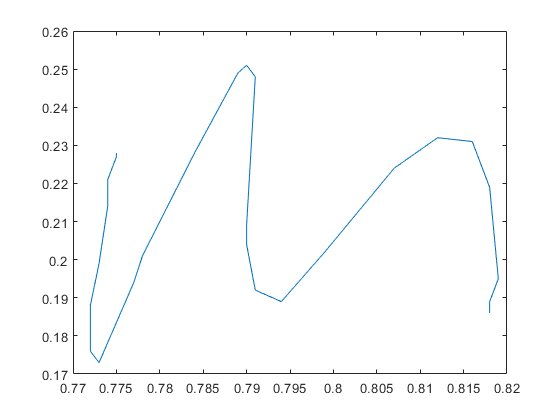

plot(data.X,data.Y)

Calling the `read` function again imports the data from the next file in the datastore.

## Task 4

Import and plot the data from the second file.

data=read(letterds)

data = 81×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    53823    0.756    0.346    0.005
    53832    0.756    0.347    0.108
    53833    0.756    0.347    0.108
    53853    0.756    0.348    0.208
    53903    0.756    0.347    0.429
    53918    0.756    0.344    0.608
    53935    0.755    0.338     0.72
    53950    0.754    0.328    0.829
    53968    0.754    0.316    0.888
    53983    0.753    0.307    0.919
    54003    0.752    0.292    0.968
    54017    0.752    0.284    0.985
    54033    0.751    0.274    0.997
    54050    0.751    0.271        1
    54067    0.751    0.268        1
    54082    0.751    0.268        1


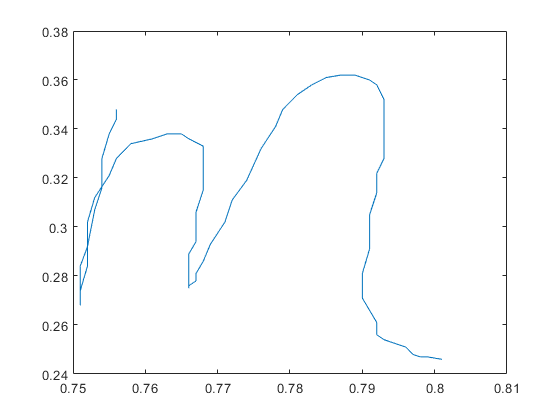

plot(data.X,data.Y)

The `readall` function imports the data from all the files in the datastore into a single variable.

## Task 5

Use the `readall` function to import the data from all the files into a table called `data`. Visualize the data by plotting `Y` against `X`.

data = readall(letterds)

data = 5774×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    34806    0.775    0.228    0.042
    34808    0.775    0.227    0.255
    34808    0.775    0.227    0.255
    34825    0.774    0.221     0.44
    34833    0.774    0.214    0.569
    34850    0.773    0.199    0.745
    34866    0.772    0.188      0.8
    34886    0.772    0.176    0.851
    34900    0.773    0.173     0.88
    34944    0.777    0.194    0.894
    34949    0.778    0.201    0.896
    34975    0.784    0.228    0.899
    34995    0.789    0.249    0.923
    35000     0.79    0.251    0.931
    35018    0.791    0.248    0.995
    35058     0.79    0.209        1


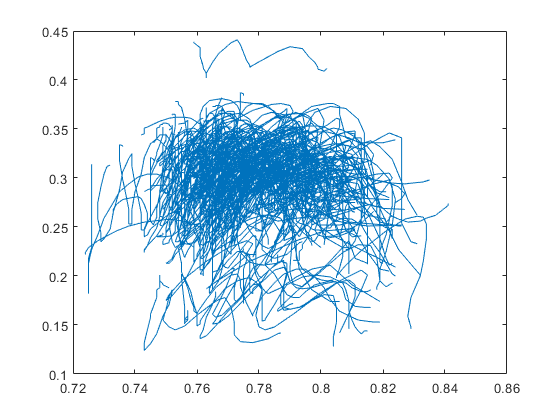

plot(data.X,data.Y)

## Further Practice

Try importing data from the files that hold samples of the letter V.

Previously, you performed some preprocessing to each letter. However, note that when you use `readall`, there's no simple way to determine where the data from one file ends and the data from the next file begins. What happens if you try to preprocess all the letters together?